clear 

% change this to save results somewhere else

if(ismac | isunix)
    root_dir = ['/Users/' getenv('USER') '/Desktop/tmp'];
else
    root_dir = [getenv('UserProfile') '\Desktop\tmp'];
 end

if(~exist(root_dir,'dir') || ~exist(fullfile(root_dir,'demo_data'),'dir'))
    mkdir(root_dir);
    disp('downloading sample data from bitbucket.org site');

## download the dataset

    urlwrite('https://bitbucket.org/huppertt/nirs-toolbox/downloads/demo_data.zip', ...
        [root_dir filesep 'demo_data.zip'])
    % This command will download the demo_data.zip file from the server.  This
    % step can be skipped if you already downloaded this. This could take a few minutes if your internet conenction is slow
    % The file is about 90Mb in size.
    
    % unzip the data
    unzip([root_dir filesep 'demo_data.zip'],[root_dir filesep]);
    % This will unpack a folder called "data" containing two groups (G1 & G2).
    % A script "simulation.m" is included which was used to generate the data
    % (but is not intended to be run).  The data was simulated from a set of
    % experimental resting state NIRS data with simulated evoked responses
    % added to it to demostrate this analysis pipeline.
    
else
    disp(['Data found in: ' root_dir ': skipping download']);
end

Data found in: /Users/theodorehuppert/Desktop/tmp: skipping download


## load data

this function loads a whole directory of .nirs files. The second argument tells the function to use the first level of folder names to specify group id and to use the second for subject id.

raw = nirs.io.loadDirectory([root_dir filesep 'demo_data' filesep 'data'], {'group', 'subject'});

Loading /Users/theodorehuppert/Desktop/tmp/demo_data/data/G1/S11/scan.nirs
Loading /Users/theodorehuppert/Desktop/tmp/demo_data/data/G1/S12/scan.nirs
Loading /Users/theodorehuppert/Desktop/tmp/demo_data/data/G1/S13/scan.nirs
Loading /Users/theodorehuppert/Desktop/tmp/demo_data/data/G1/S15/scan.nirs
Loading /Users/theodorehuppert/Desktop/tmp/demo_data/data/G1/S17/scan.nirs
Loading /Users/theodorehuppert/Desktop/tmp/demo_data/data/G1/S19/scan.nirs
Loading /Users/theodorehuppert/Desktop/tmp/demo_data/data/G1/S22/scan.nirs
Loading /Users/theodorehuppert/Desktop/tmp/demo_data/data/G1/S23/scan.nirs
Loading /Users/theodorehuppert/Desktop/tmp/demo_data/data/G1/S27/scan.nirs
Loading /Users/theodorehuppert/Desktop/tmp/demo_data/data/G1/S28/scan.nirs
Loading /Users/theodorehuppert/Desktop/tmp/demo_data/data/G1/S29/scan.nirs
Loading /Users/theodorehuppert/Desktop/tmp/demo_data/data/G1/S30/scan.nirs
Loading /Users/theodorehuppert/Desktop/tmp/demo_data/data/G1/S32/scan.nirs
Loading /Users/theodorehu


% The load directory function will load *.nirs data files based on hierarchical folder information.  
% The second argument in the function describes how to interpret this hierarchical information.
% Example 1:
%      <root folder> / <Group 1> /
%                                   <subject A>/ files.nirs
%                                   <subject B>/ files.nirs
%                    / <Group 2> /
%                                   <subject C>/ files.nirs
%                                   <subject D>/ files.nirs
%
% the full path to <root folder> should be first input.  The second input should be {'group','subject'}.  
% This will result in the data being organized into two groups with two subjects per group.
%
% Example 2:
%      <root folder> / <Group 1> /
%                                   <subject A>/ <Session 1> / files.nirs
%                                              / <Session 2> / files.nirs
%                                   <subject B>/ <Session 1> / files.nirs
%                                              / <Session 2> / files.nirs
%                    / <Group 2> /
%                                   <subject C>/ <Session 1> / files.nirs
%                                              / <Session 2> / files.nirs
%                                   <subject D>/ <Session 1> / files.nirs
%                                              / <Session 2> / files.nirs
%
% the full path to <root folder> should be first input.  The second input should be {'group','subject','session'}.  
% This will result in the data being organized into two groups with two subjects per group and two sessions per subject.
% 
% The group/subject/etc labels are aribitrary (e.g. you can name them
% whatever you wish) but define the demographics information avaliable for
% the later group-level ANOVA and mixed effects models.  

% You can view the demographics information for your data by typing:
demographics = nirs.createDemographicsTable(raw);
% This information is stored in the new Matlab table class (see Matlab
% "help table").  This data can be displayed in a formated message 
% >> disp(demographics);  

% This should show two columns (for the 68 data files provided)
%    group    subject
%     _____    _______
%     'G1'     'S11'  
%     'G1'     'S12'  
%     'G1'     'S13'  
%     'G1'     'S15'  
%     'G1'     'S17'  
%     'G1'     'S19'  
%     'G1'     'S22'  
%     'G1'     'S23'

## The nirs.core.Data structure.

The data (now contained in the variable "raw") is contained within a Matlab class definition that we have created. A Class is an object that may contain both public (accessible to other programs) and private (internal) variables and methods. The matlab command "methods(raw)" or methods(nirs.core.Data) will display a list of the methods that this class can use. For the Data class, these methods include draw() and a number of variables. For example, the command "raw(1).draw()" will evoke the drawing routine for the first data file. 

The "raw" variable is an array of class nirs.core.Data. This allows array operations to be preformed. E.g. raw(2)=[]; would remove the 2nd data file (and shift the entries down); raw = [dataset1 dataset2]; would concatinate two data sets. 

% The first data file looks like this:
% % >> raw(1)
% ans = 
%   Data with properties:
%      description: '/Users/lab/Desktop/tmp/data/G1/S11/scan.nirs'
%             data: [3505x70 double]
%            probe: [1x1 nirs.core.Probe]
%             time: [3505x1 double]
%               Fm: 0
%         stimulus: [1x1 Dictionary]
%     demographics: [1x1 Dictionary]
%               Fs: 10

%  The data class itself contains subclasses (e.g. Dictionary and nirs.core.Probe) 
%  that will be explained later in this tutorial.  This file has 3501 time points sampled at Fs=10Hz.  
% It's a CW-NIRS measurement (e.g. Fm =0).  There are 70 channels of data.

## The nirs.core.Probe class

The probe class describes the probe layout and measurement info for the 70 channels.

raw(1).probe ans = Probe with properties:

% The srcPos and detPos are the [X.Y.Z] location of the source and
% detectors used for drawing
% probe.distances is a read-only field that is automatically calculated
% from the src/det positions
% probe.link is a Matlab table class (just like the demographics variable
% above).  
% probe.link in this example will look like this:
%    source    detector    type
%     ______    ________    ____
%      1         1          690 
%      1         1          830 
%      1         2          690 
%      1         2          830 
%      1         6          690 
%      1         6          830

## The Dictionary class

The Dictionary class is a book-keeping method that we invented for this toolbox. Basically, a Dictionary object is an array that is indexed by a name (string) instead of a subscript. E.g. MyDictionary = Dictionary(); % Create an empty dictionary MyDictionary('Some Name') = 1; MyDictionary('Some Other Name') = 2; % Stores data into two entries disp(MyDictionary('Some Other Name')); % --> displays "2" to the screen.

% Since there are 68 subjects in this data set, this analysis could take a
% bit of time depending on your computer.  You are welcome to try to
% analyze the whole data set, but let's prune out a bit so this runs a lot
% faster
raw = raw(1:4:end);
% This will keep only every 4th subject

## preprocessing pipeline

The nirs-toolbox is based on creating and running jobs to do the analysis. Jobs can be run one at a time or concatinated and run all at once. This list of jobs is defined in nirs.modules.* (type "help(nirs.modules)" for matlab help on this.

% Let's create an analysis pipeline.
% The first job is always intialized with an empty argument
% For our first job, lets run a routine to remove any files that aren't
% going to be used in the statistical model. 

% You can remove junk files, such as setup files here.  Any file without
% a stimulus design will be removed (e.g. resting state or files collected
% when setting the probe on the subject before the study began)
j = nirs.modules.RemoveStimless( );
% This is a simple job that doesn't take any arguments.  Showing this in
% matlab displays:
% >> disp(j)
%       RemoveStimless with properties:
%            name: 'Remove Files w/o Stim'
%            prevJob: []

% At this point, we could just run the job using the command:
% >> raw_pruned = j.run(raw);  
% But, instead, lets add more functionality to the job and run it all at
% once later.

% Now, lets add a second step/job to the pipeline by chaining the jobs together
% This is done by feeding the current job in as the argument when creating
% a new job.  E.g. new job  = nirs.modules.<job name>( previous job); 

% This module can be used to rename and/or merge stimulus conditions
% together. 
j = nirs.modules.RenameStims( j );
% This job contains a field called "listOfChanges" 
% which specifies the changes we are going to make to the stimulus names;  

% The matlab command:
% >> unique(nirs.getStimNames(raw));  % will show a list of all the unique names
% of stimulus events in the raw data.  
% You can see there are two conditions "A" & "B" right now.  Let's change
% the names to "X" and "Y" instead to show how.
j.listOfChanges = {
    'A', 'X'; 
    'B', 'Y'};
% Now when we run the job, the condition names will be changed.
% Likewise, this would merge the two conditions into a single condition
% j.listOfChanges = {
%     'A', 'X'; 
%     'B', 'X'};

% There are also jobs:
%  nirs.modules.DiscardStims - removes a set of conditions
%  nirs.modules.KeepStims - removes all except a set of conditions

% Note- these steps do not touch the original data files.  If you reloaded
% the raw data files, you would have to start renaming all over again


% Now, let's try some processing.  The next step will be to resample the
% data. 
% If the data is sampled at a very high sampling frequency, resampling to
% around 4 or 5 Hz will speed up the regressions which run line O(N^2). It's recommended that you
% choose a new sampling rate that you choose a new sampling frequency such
% that old_fs / new_fs is an integer (e.g. 20 Hz -> 5 Hz).
j = nirs.modules.Resample( j );
j.Fs = 2;  % Sets the new sample rate to 2Hz (was 10Hz).  Usuaully, I would leave the sample rate
% at 4Hz or above, but for the purposes of allowing this demo to run
% quickly, let's use 2Hz.

% Many times you can have files excessive baselines before the start or at
% the end of an experiment for various reasons.  Here we can trim the data
% so that there is a max of 30 seconds of pre and post baseline.  This will
% cut off the time points earlier then 30s before the first stim event in the data and 30s AFTER the last stim event.
j = nirs.modules.TrimBaseline( j );
j.preBaseline  = 30;
j.postBaseline = 30;
% or j.postBaseline = []; would keep all the data AFTER the last stim event
% and only discard the pre-event times.


% Before doing regression we must convert to optical density and then
% hemoglobin.  The two modules must be done in order.
j = nirs.modules.OpticalDensity( j );

% Convert to hemoglobin.
j = nirs.modules.BeerLambertLaw( j );


% Finally, run the pipeline on the raw data and save to anew variable.
% This will run through all the steps we just created and output the
% processed nirs.core.Data class (which is now hemoglobin since the MBLL
% was now run);
hb = j.run( raw );
% This new data variable is the same class as the raw variable and has the
% same methods and fields.  But, now we can see that this stores hemoglobin
% If we look in the probe.link field, the type is now hbo & hbr
% >>disp(hb(1).probe.link)
%     source    detector    type 
%     ______    ________    _____
%      1         1          'hbo'
%      1         1          'hbr'
%      1         2          'hbo'
%      1         2          'hbr'
%      1         6          'hbo'

## check data for QA

Here you can click through the files and also click on the probe to see specific channels. >> nirs.viz.TimeSeriesViewer( hb ); % This function will show the GUI to see the hb data

% Alternatively, we can use the command:
% >> hb(1).draw();  to display just the furst file

## subject level pipeline

% Now, let's start a new job and run the GLM model 

% This is the recommended first-level GLM module.
j = nirs.modules.GLM();  % remember, creating a job with no input will start a new job.  
% We could have just kept adding the the old job if we had wanted to
% We can see that this job has a number of fields
%  disp(j)
%   AR_IRLS with properties:
%          basis: [1x1 Dictionary]  -- This field describes the canonical or deconvolution model
%        verbose: 1  -- This is a flag to display more info to the screen
%     trend_func: @nirs.design.trend.constant  -- This field describes trend regressors
%           name: 'GLM via AR(P)-IRLS'
%        prevJob: []
       

%%%% (OPTIONAL) This turns on optional progress output.
j.verbose = true;

%%%% (OPTIONAL) The temporal model must include trend regressors, such as 
% DCT terms or polynomials.  At the very least, a constant regressor must be 
% returned, which is set by default.
% The j.trend_func field is a function handle which inputs a time vector
% There are several options for this which are stored under
% nirs.design.trend.*

% This is a function of t that returns a third order polynomial trend terms.
% >> j.trend_func = @(t) nirs.design.trend.legendre(t, 3);

% This example specifies DCT terms with a frequency cutoff of 0.08.
j.trend_func = @(t) nirs.design.trend.dctmtx(t, 0.08);

% This example returns only a constant.  You could also just use a 0th
% order polynomial as above.
% >> j.trend_func = @nirs.design.trend.constant;

%Let's use the DCT regressor for now;
% typing >> "plot(j.trend_func([0:60]'));"  will plot the DCT for
% time=0-60s

%%%% (OPTIONAL) A temporal basis can be specified. The Canonical HRF basis
% used by default.
j.basis = Dictionary();

% the default basis will be used if no other basis is specified
j.basis('default') = nirs.design.basis.Canonical();

% optionally, you can specify a different basis for each condition
j.basis('X') = nirs.design.basis.Canonical();
j.basis('Y') = nirs.design.basis.Canonical();

% other bases included nirs.design.basis.*
% nirs.design.basis.BoxCar();  -- This is a simple box car based on the stim timing
% nirs.design.basis.FIR();  -- This is the finite-impulse response (or
%                              deconvolution model).
% nirs.design.basis.GAMMA();  -- This is the SPM gamma function 

% Run the analysis.  This could take some time if your computer is terribly slow.  
% If you want, you can go back up and change the sample rate to 1Hz in the
% resample function and it should run 25x faster.
SubjStats = j.run( hb );

.....................................Finished    1 of   17.
.....................................Finished    2 of   17.
.....................................Finished    3 of   17.
.....................................Finished    4 of   17.
.....................................Finished    5 of   17.
.....................................Finished    6 of   17.
.....................................Finished    7 of   17.
.....................................Finished    8 of   17.
.....................................Finished    9 of   17.
.....................................Finished   10 of   17.
.....................................Finished   11 of   17.
.....................................Finished   12 of   17.
.....................................Finished   13 of   17.
.....................................Finished   14 of   17.
.....................................Finished   15 of   17.
.....................................Finished   16 of   17.
.....................................Fin

% I am running this job on the hemoglobin variable, but I could have also
% done so on any nirs.core.Data variable (e.g. optical density)

% The output of this pipeline is now a new data class called
% nirs.core.ChannelStats.  This is a class which stores the SPM model
% information including all the covariance information needed to do the
% group level stats, any secondary T-stats or contrasts, image
% reconstruction, and region-of-interest definitions.

## The nirs.core.ChannelStats class

This data class >> disp(SubjStats(1)) ChannelStats with properties:

% When we first entered the data using the load function, we used the
% folder structure to define groups, subjects, etc.  These define
% demographics variables which are used for group-level mixed effects or
% ANOVA models (either in channel space or for image reconstruction).  We 
% already showed how this demographic data could be displayed using the command
%
% >> disp(nirs.createDemographicsTable(<NIRS Data class>));
% 
% This demographic infomation can also be specificed inside the *.nirs
% files themselves (see documentation on the *.nirs format). Demographics can be 
% either catagorical (like "group") or valued (like age or clinical scale) Finally, we
% can load/add additional demographics information directly from the
% command line tools.  

% To add demographics information, we use the following job:
j = nirs.modules.AddDemographics();
% This job contains a field (demoTable) that is used to populate the
% demographics.  This can be programatically or simply read from a CSV file
%
% In the demo data, we provide a CSV file with demographics info.
j.demoTable = readtable( [root_dir filesep 'demo_data' filesep 'data' filesep 'demographics.csv'] );

% We are going to match the subject column in the above table
j.varToMatch = 'subject';  
% Note "subject" (or whatever you are matching based on) needs to be an
% entry in BOTH the CSV file and the nirs.core.<> class that you are
% loading the demographics to.  

% This is a job, so we need to run it like the others.  In this case, let's
% run the job on the SubjStats variable we just created.  We could, of
% course, have ran this job earlier on the raw data
SubjStats = j.run(SubjStats);

% Just like before, we can check the demographics by using
disp(nirs.createDemographicsTable( SubjStats ));

    group    subject    age
    _____    _______    ___

    'G1'      'S11'      28
    'G1'      'S17'      99
    'G1'      'S27'      27
    'G1'      'S32'      70
    'G1'      'S4'       60
    'G1'      'S46'      88
    'G1'      'S50'      12
    'G1'      'S62'      18
    'G1'      'S68'      90
    'G2'      'S14'      75
    'G2'      'S20'       9
    'G2'      'S26'       2
    'G2'      'S34'     100
    'G2'      'S42'      44
    'G2'      'S52'      32
    'G2'      'S59'      62
    'G2'      'S64'      90



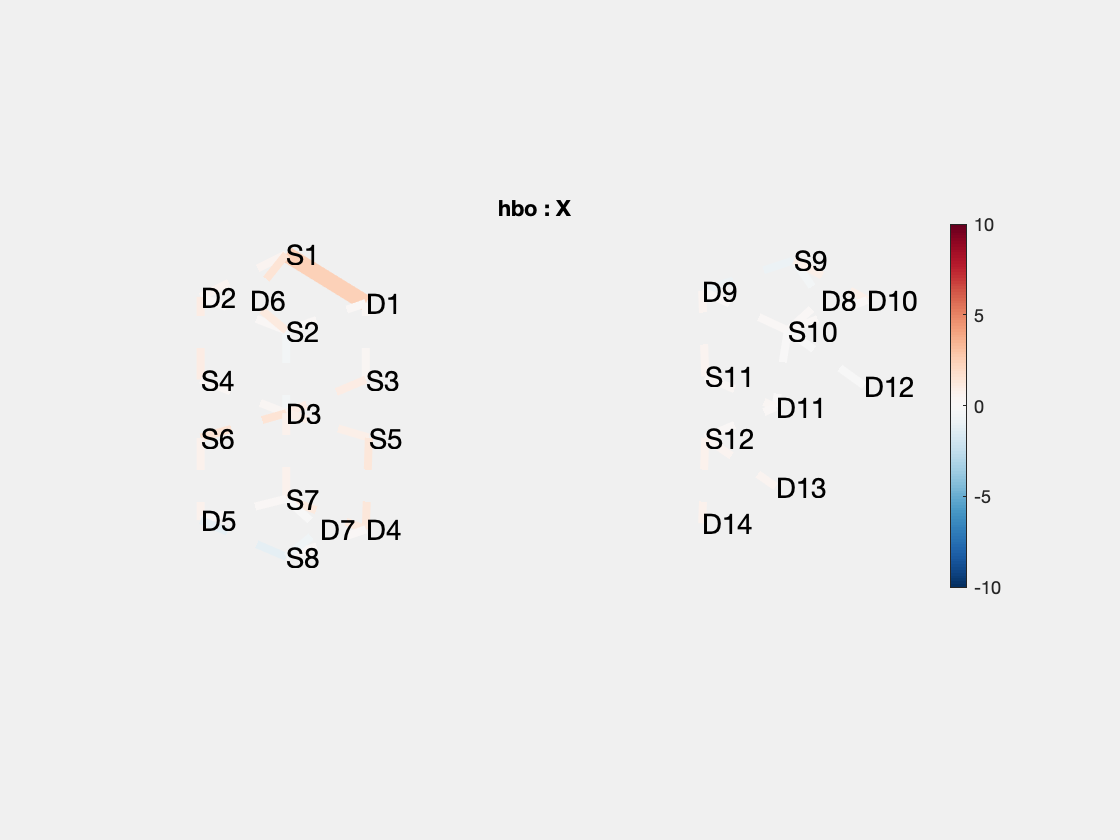

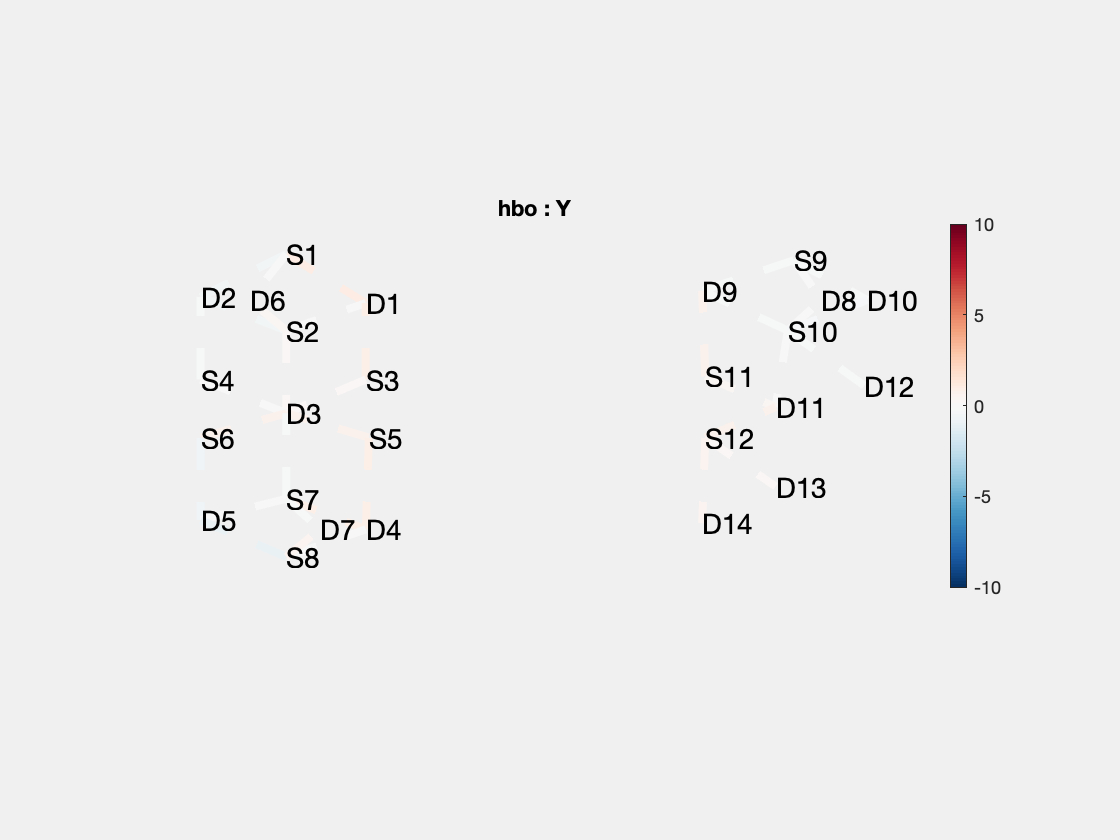

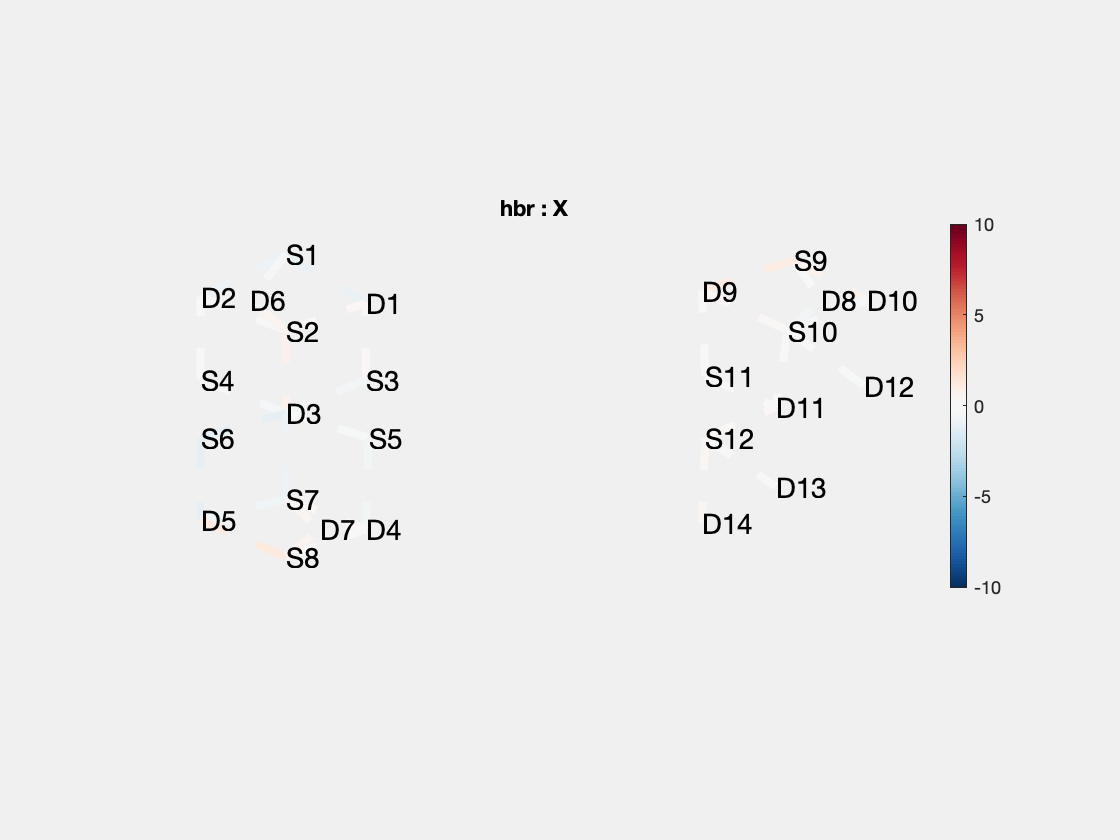

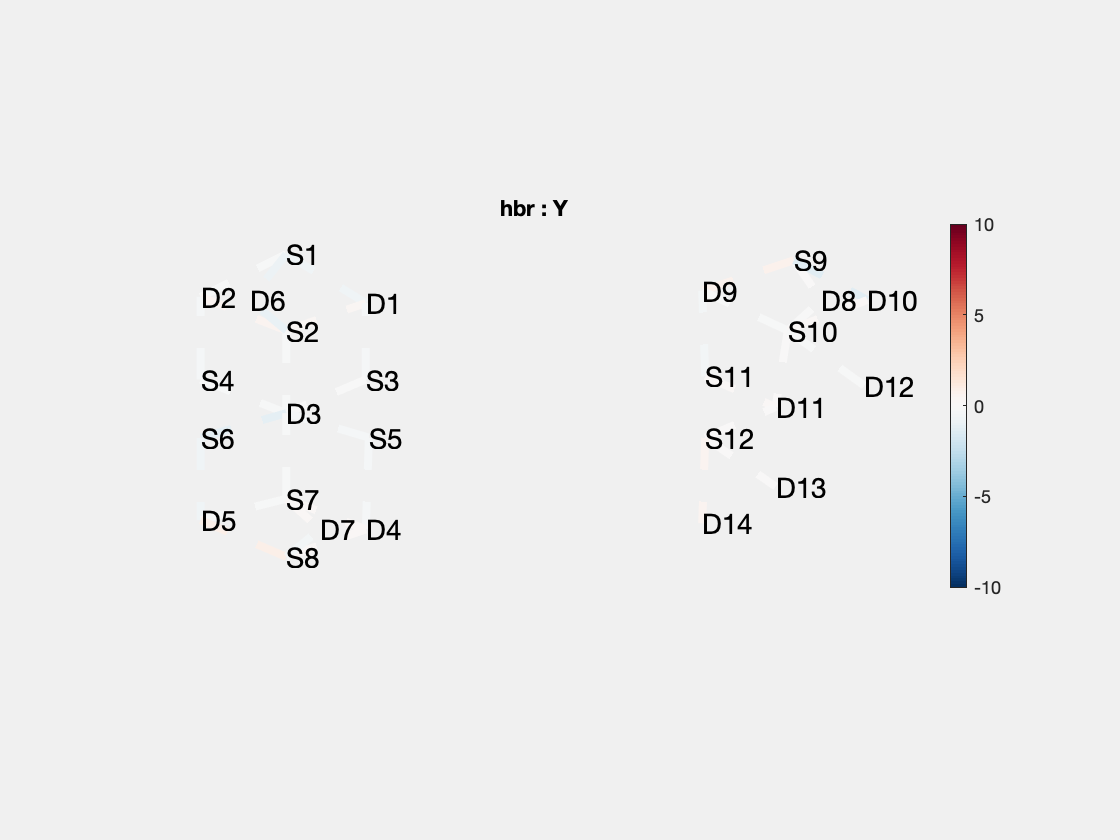

% and we can see that a new column called "age"
% Note, we just made this information up for the purpose of this demo
%
%     group    subject    age
%     _____    _______    ___ 
%     'G1'     'S11'       28
%     'G1'     'S12'       72
%     'G1'     'S13'       99
%     'G1'     'S15'        4
%     'G1'     'S17'       99
%     'G1'     'S19'       62
%     'G1'     'S22'      100
    
% The ChannelStats class has an entry per file, so right now we should have 68 
% entries.  These are the stats for each of the files from the raw data.
% Just like the nirs.core.Data class, the ChannelStats class is an array
% and can be concatinated or deleted using sub-indexing.  
% 
% You could the data in batches and later concatinate the files such as:
% >> StatsAll = [Stats_from_year1 Stats_from_year2];  
% Thus, you wouldn't need to rerun the analysis as new subjects are added.
%
% The ChannelStats class has a draw function (similar to the data class)
% To draw the data, you use the command:
SubjStats(1).draw('tstat', [-10 10], 'p < 0.05');

% You should get 4 images for conditions X & Y and HbO2 & Hb
% Note, you have to tell the index (1 in this case) because the data is an
% array.
%  This notation used in the draw command will display the T-stat (other options are "F-stat" and
%  "beta").  This will scale from -10 to 10 and will only show data for
%  p<0.05.  
%  
% The ChannelStats variable can be used to run t-tests to create different
% contrats (e.g. condition A vs B), but we will show some more examples of this in a little bit.

## Group level

Now, let's run the group level model to combine the 68 files. This module computes group level statistics using a mixed effects model.

j = nirs.modules.MixedEffects( );

% We must specify the formula for the mixed effects.  This one calculates
% the group mean for each condition.  There is also a random intercept for
% each subject.  Google "matlab wilkinson notation" or see
% <http://www.mathworks.com/help/stats/wilkinson-notation.html> for more examples.
j.formula = 'beta ~ -1 + group:cond + (1|subject)';
% In this case, we will obtain a total of 4 images (x2 for oxy- and
% deoxy-Hb) because group and condition are being considers.  
%  Condition X - For Group G1
%  Condition X - For Group G2
%  Condition Y - For Group G1
%  Condition Y - For Group G2

% Here we must specify the encoding for categorical variables, such as
% group and condition.  Options are 'full', 'reference', 'effects'. 
j.dummyCoding = 'full';

% We could also add demographics to the model, such as age, gender, etc.
j.formula = 'beta ~ -1 + group:cond + age + (1|subject)';
j.include_diagnostics=true;
% In this case, I will have 5 images.  In addition to the 4 above, I will
% also have a map of channels that are significantly explianed by the age
% cofactor

% Run the group level. This could take awhile depending on your computer.
GroupStats = j.run(SubjStats);
% The output of this is anouther ChannelStats class variable (just like our
% previous SubjStats).

## vizualization

We can look at the results like below. This tells it to draw the probe using tstat values, showing a range of -10 to 10 and using p < 0.05 as the criteria for statistical significance.

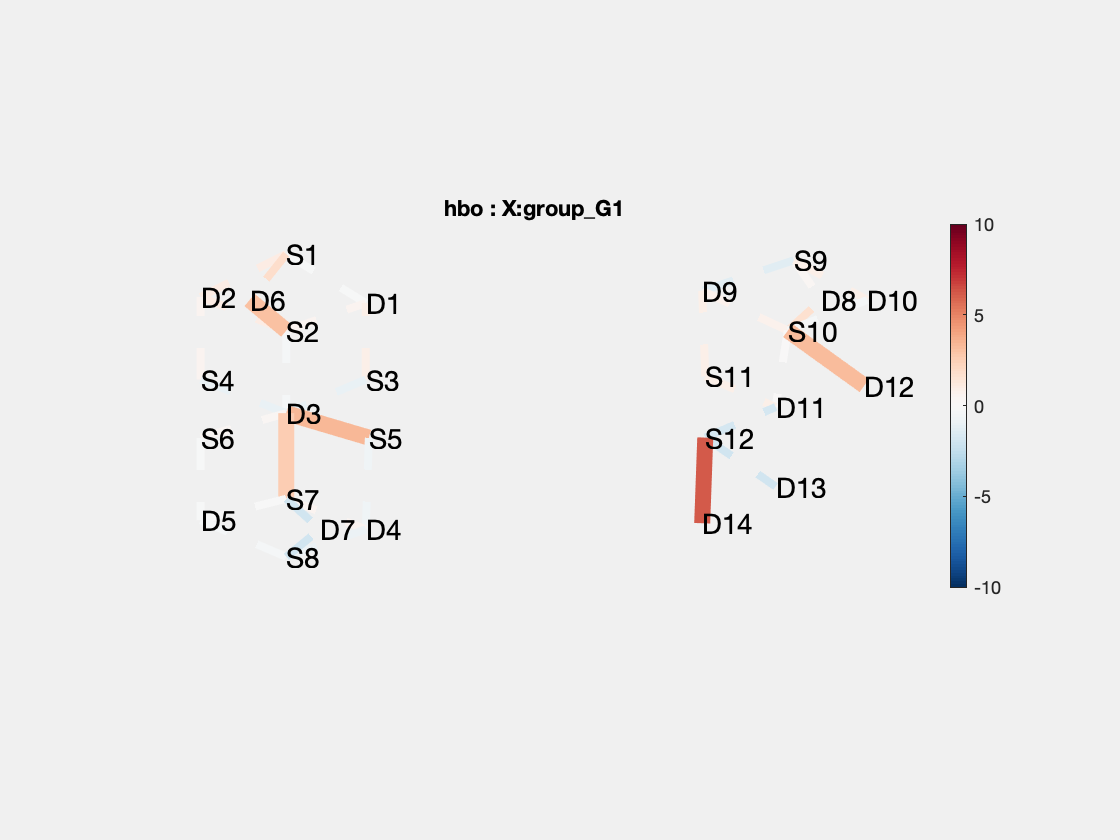

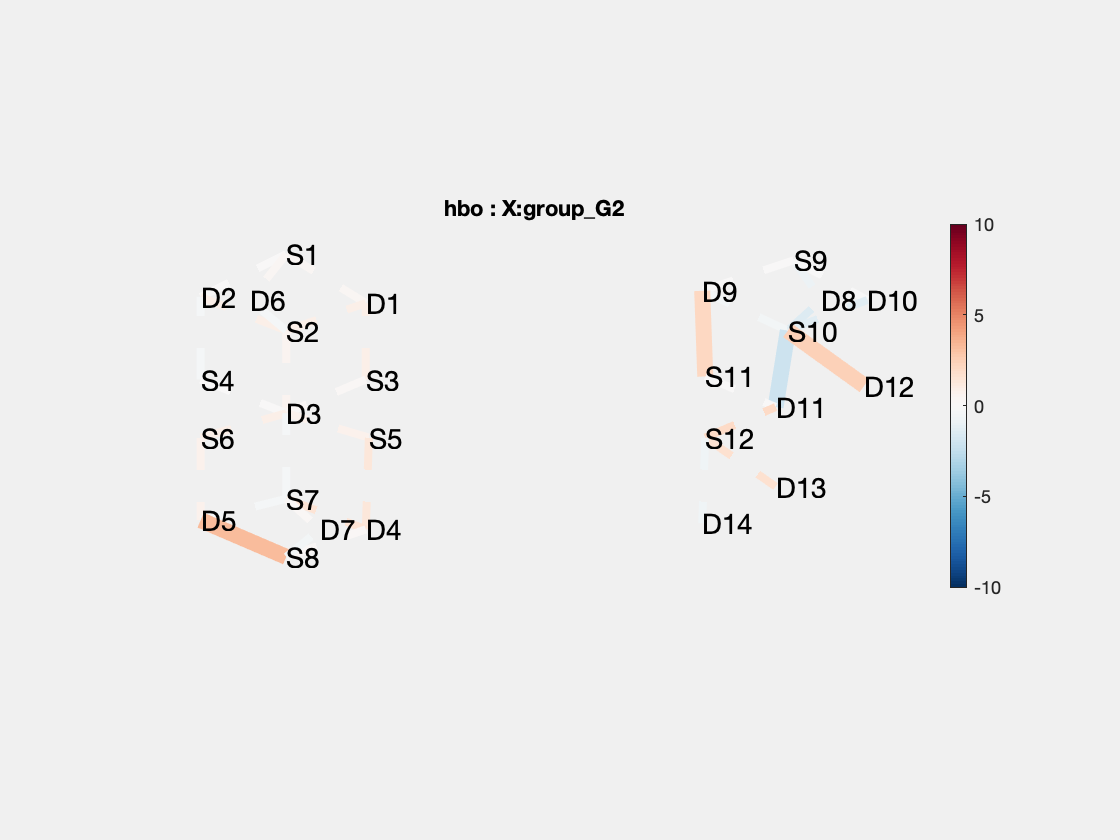

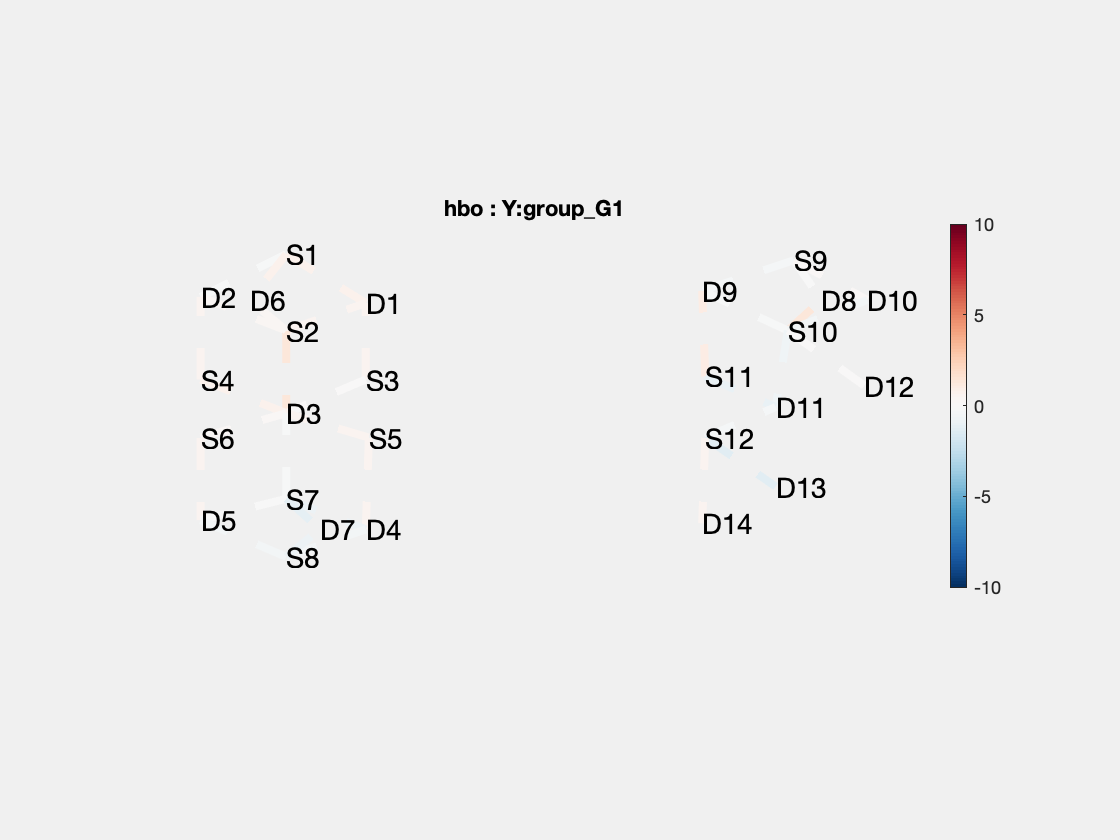

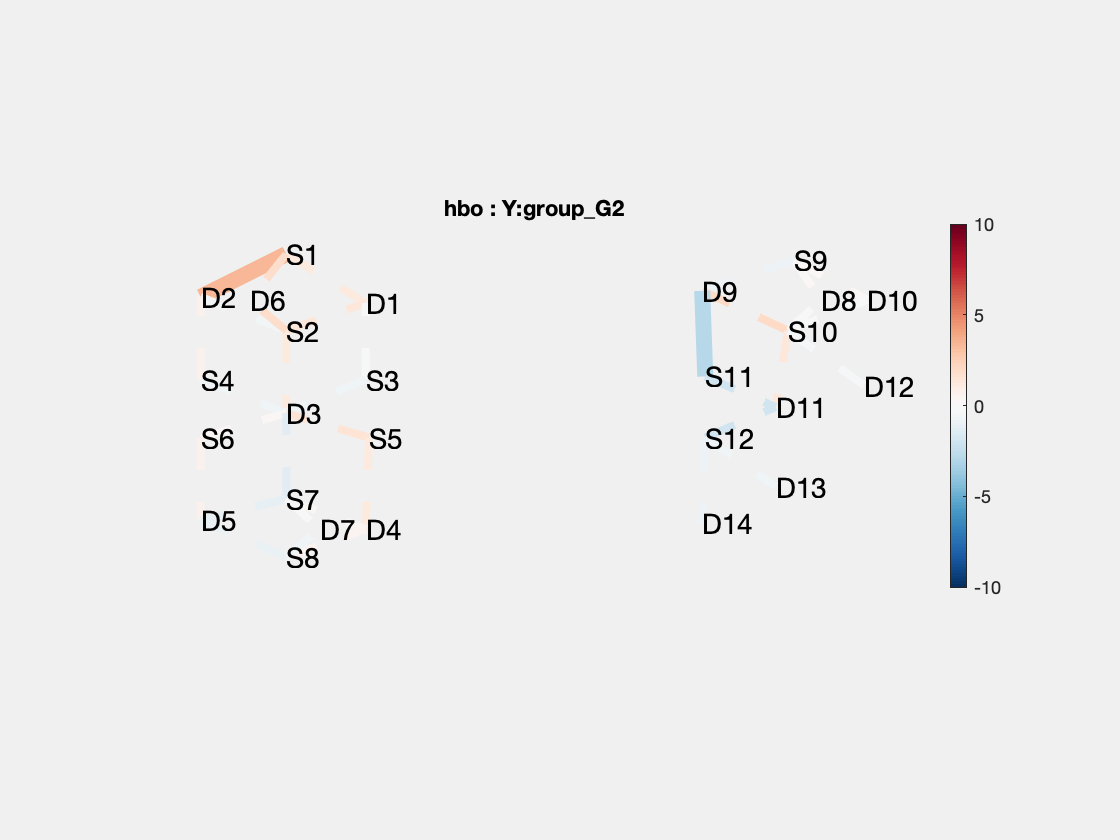

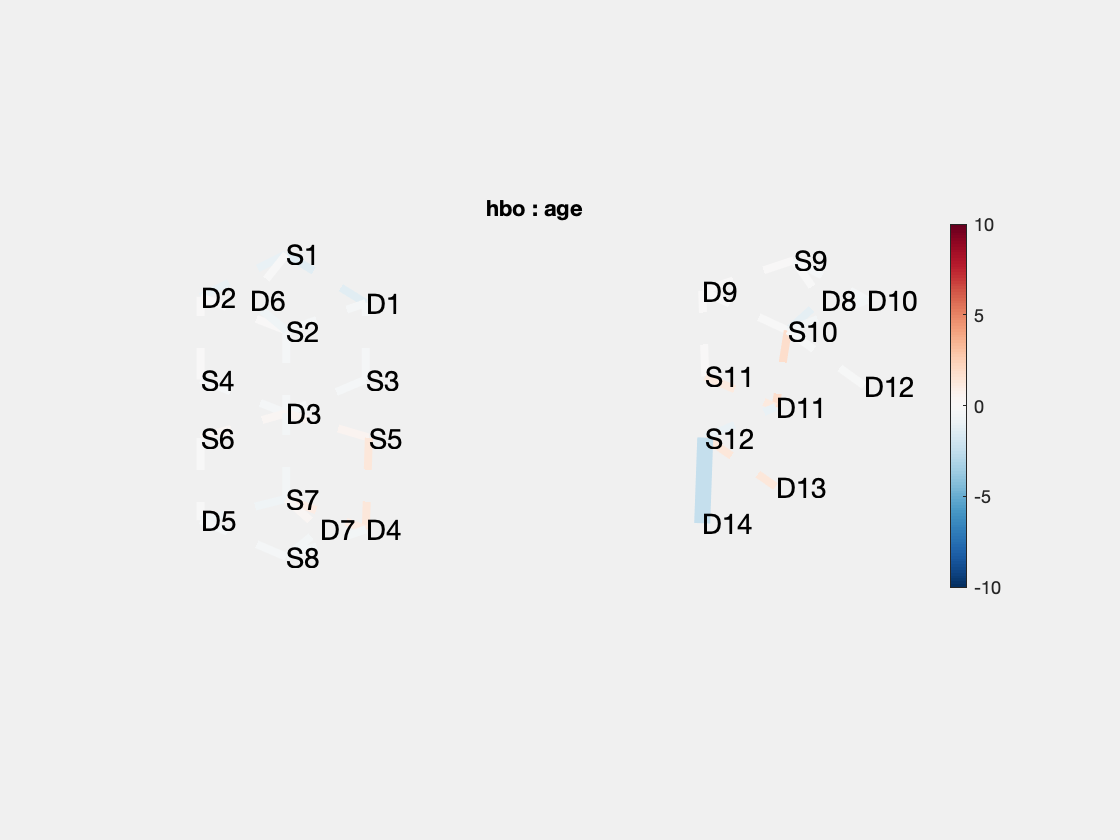

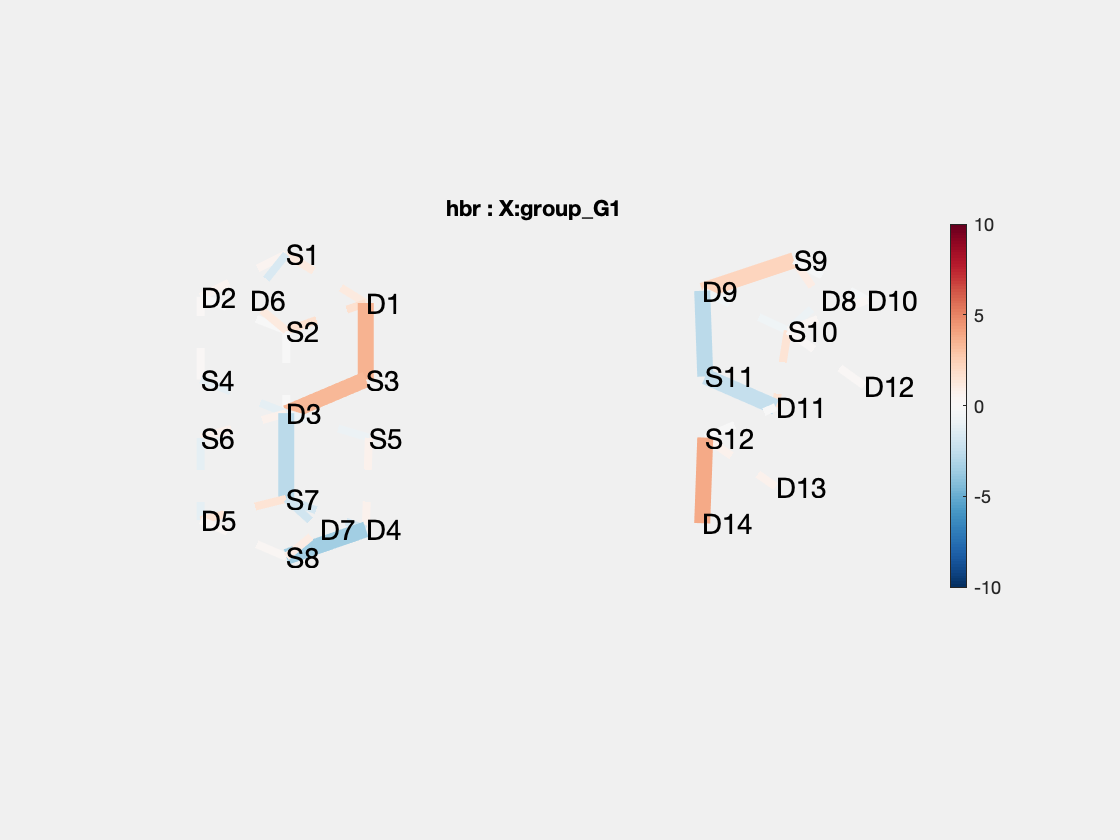

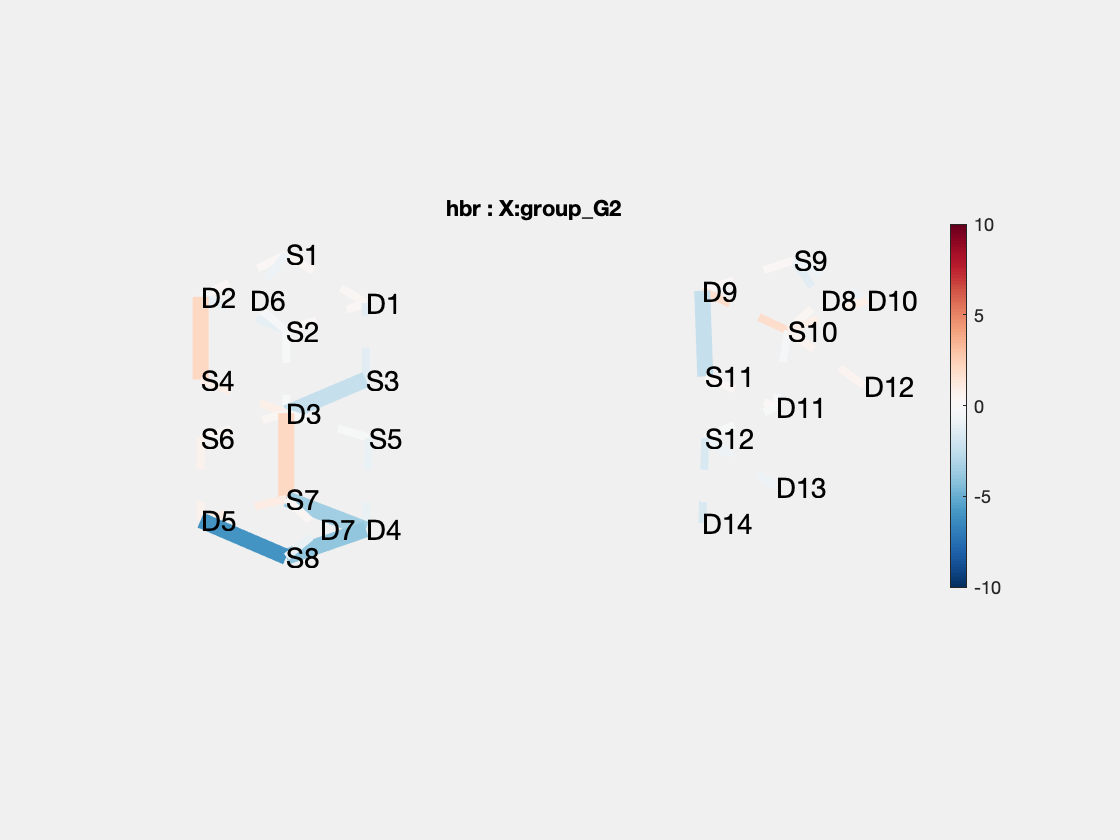

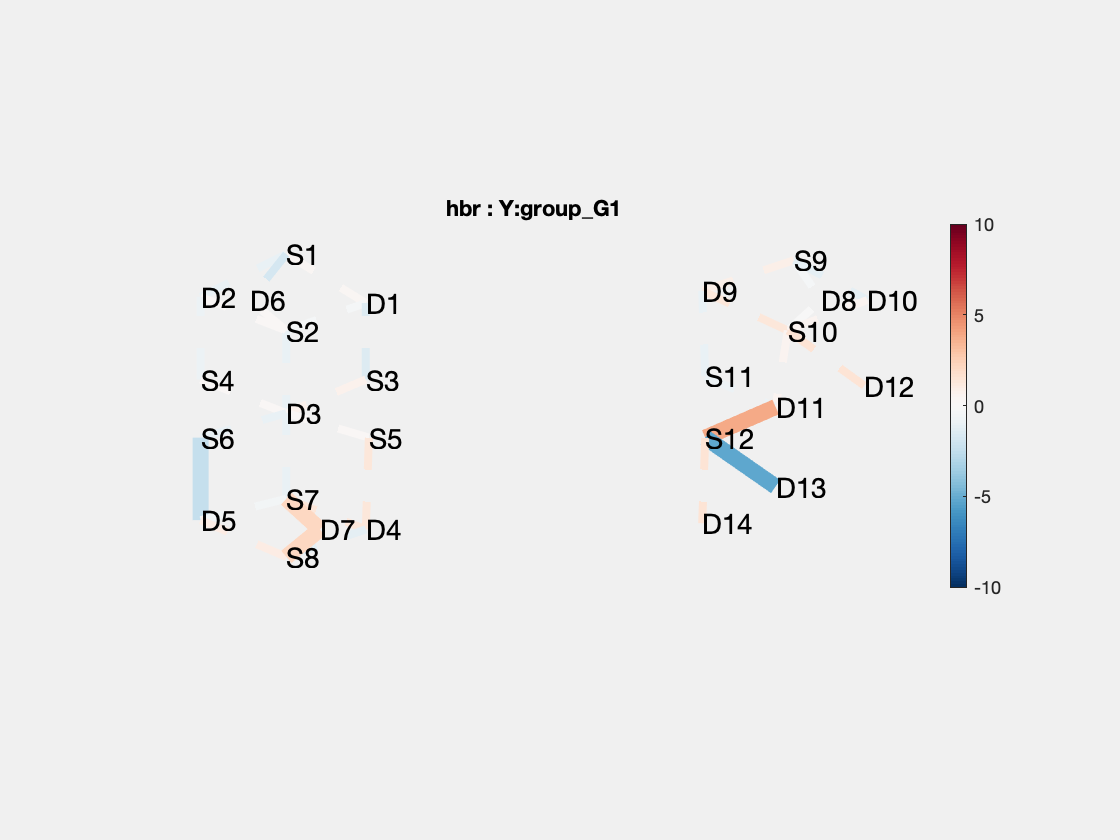

ans =   1×10 Figure array:

    Figure    Figure    Figure    Figure    Figure    Figure    Figure    Figure    Figure    Figure


GroupStats.draw('tstat', [-10 10], 'p < 0.05')

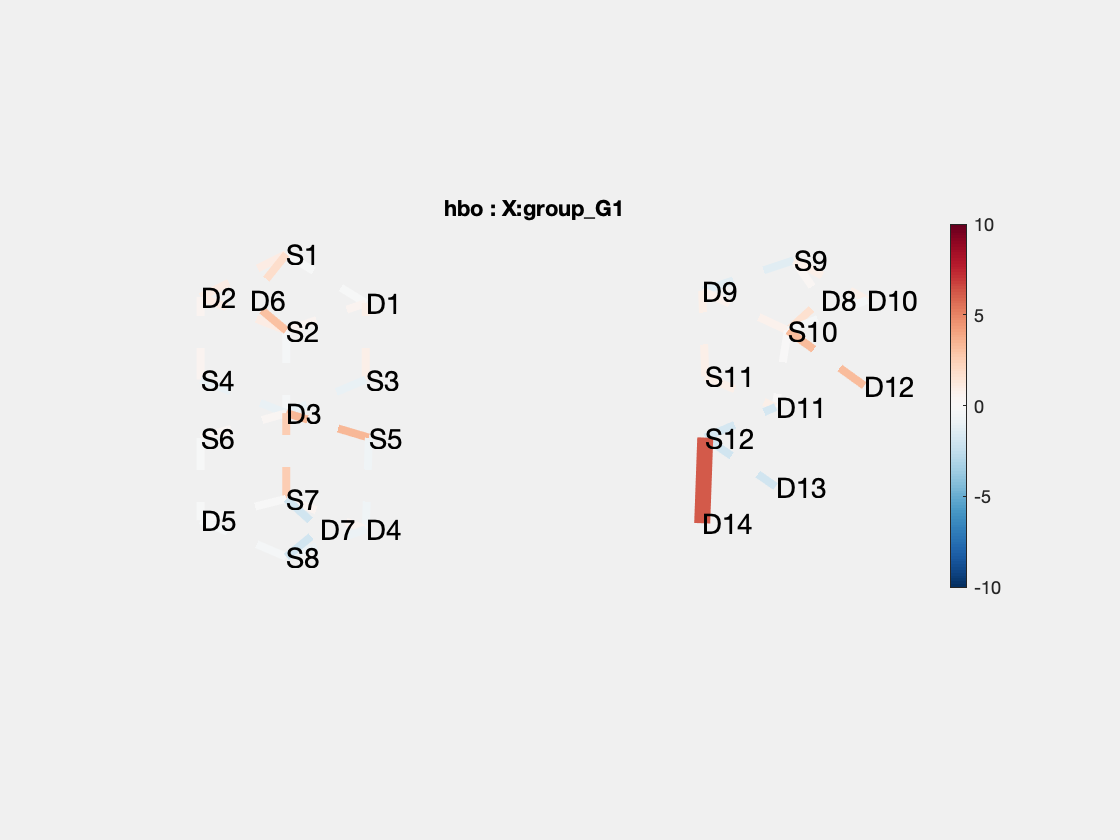

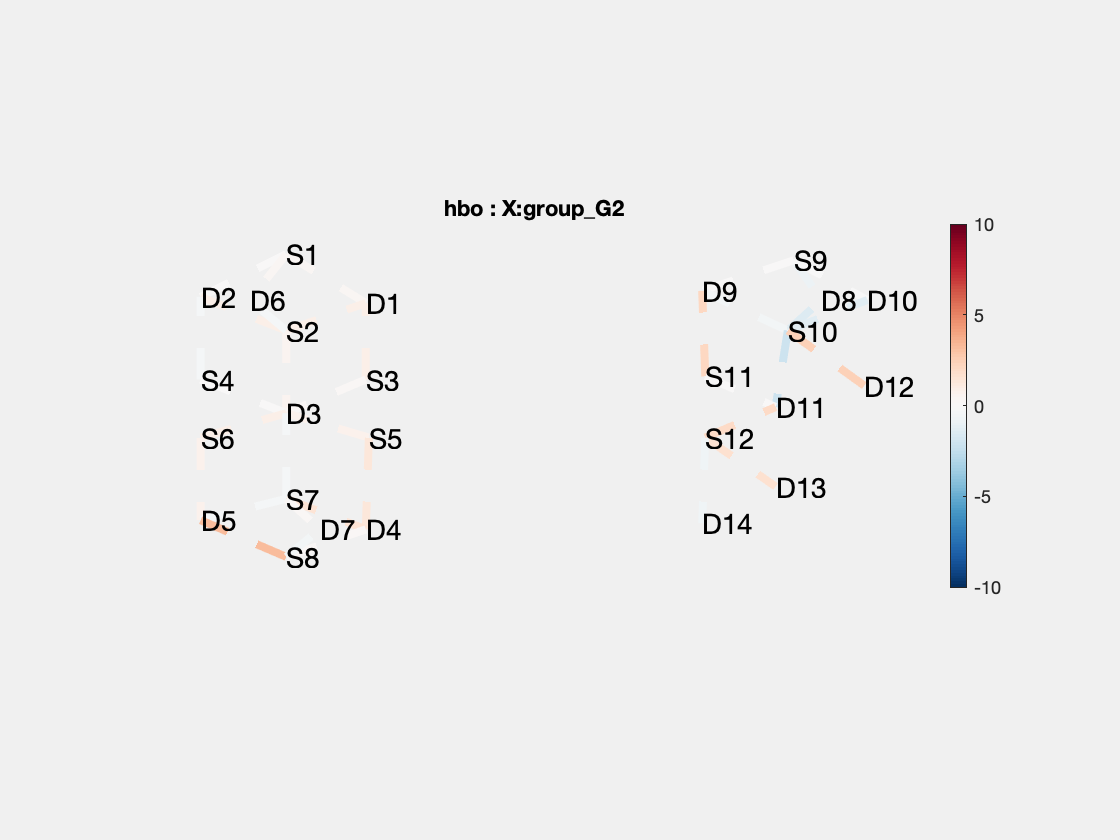

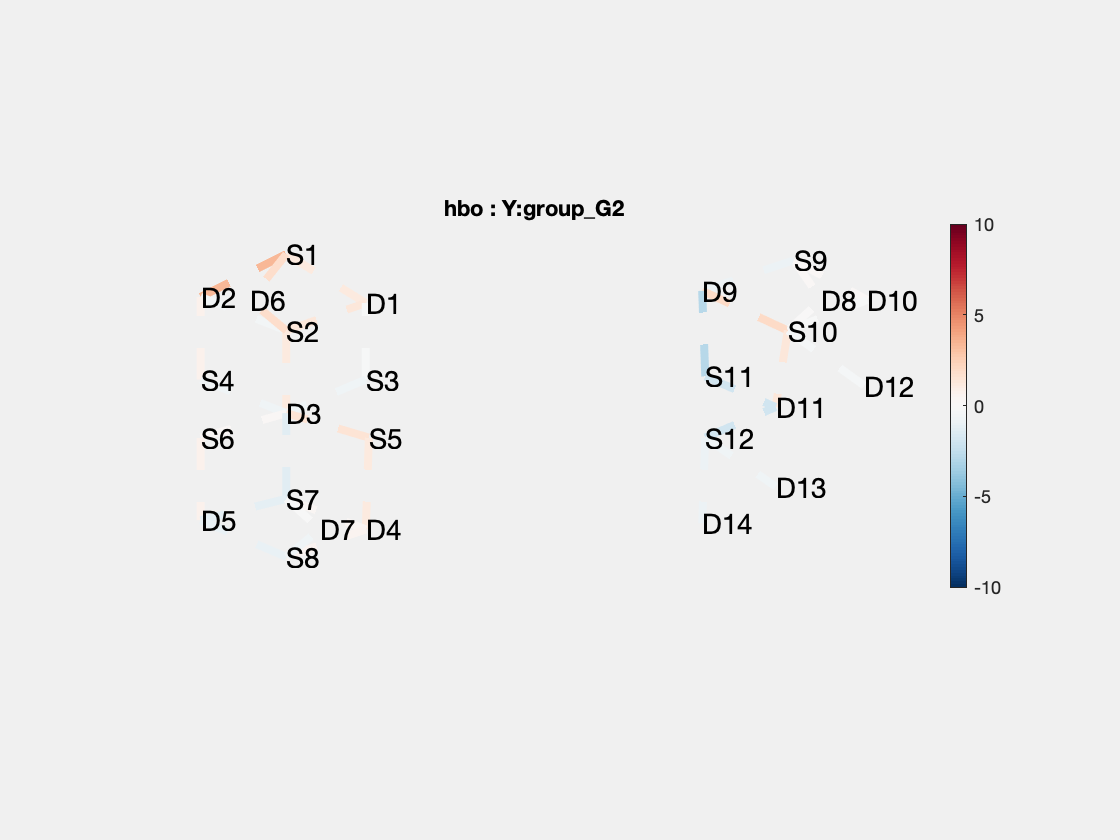

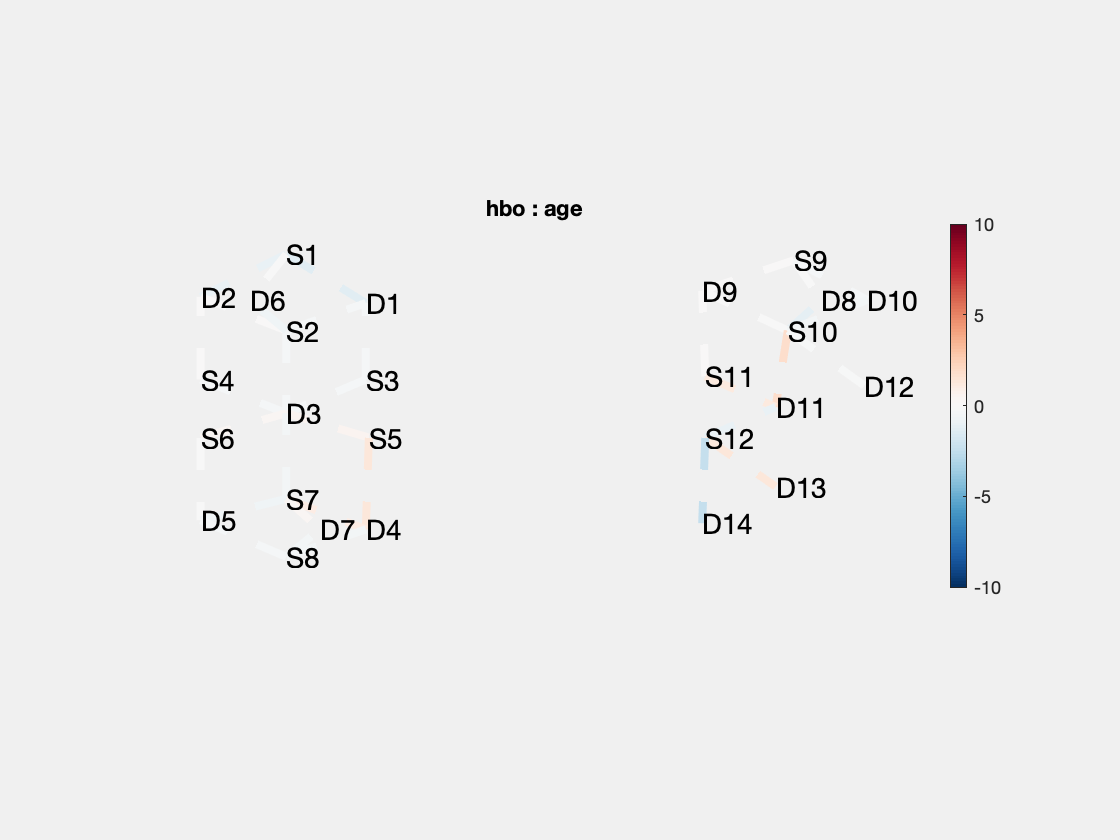

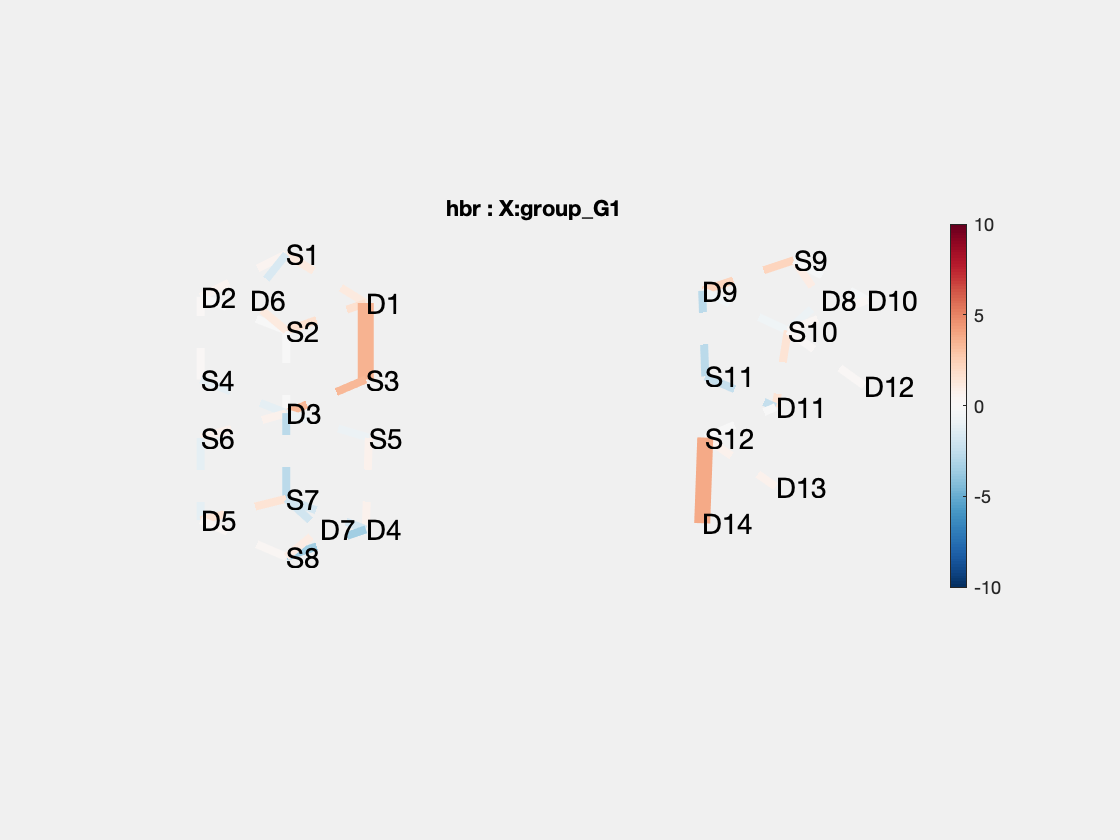

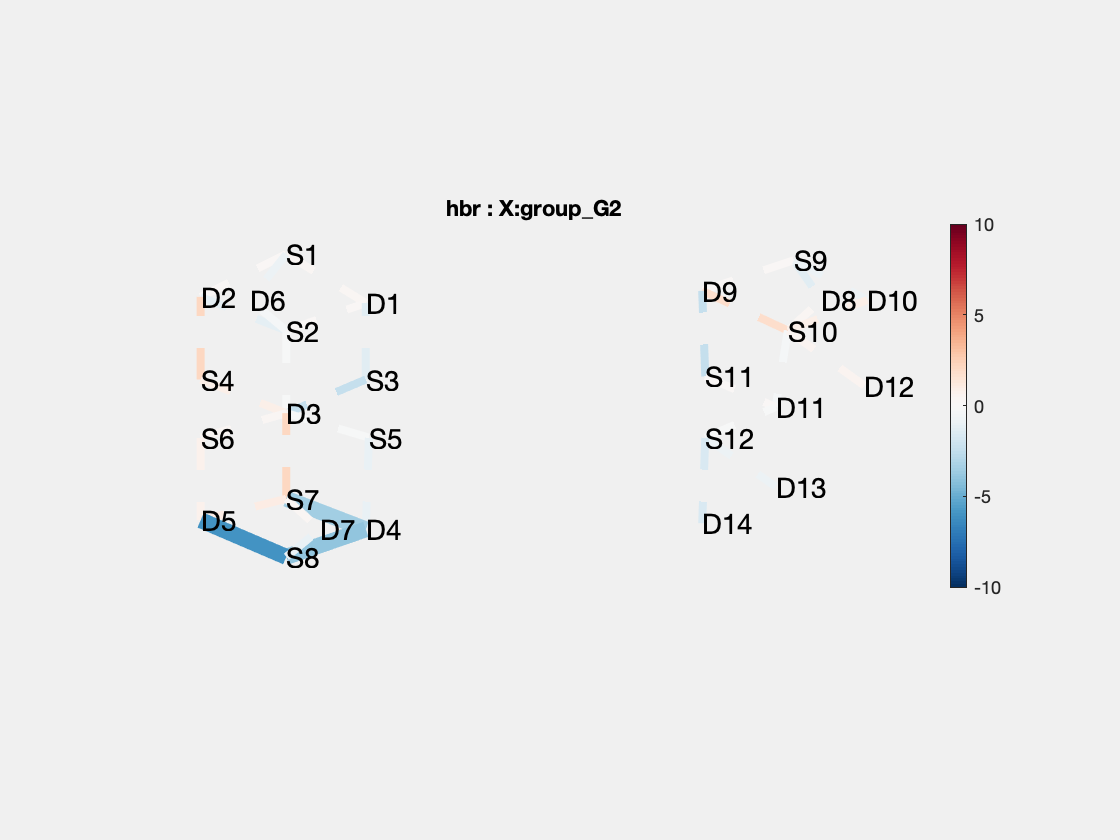

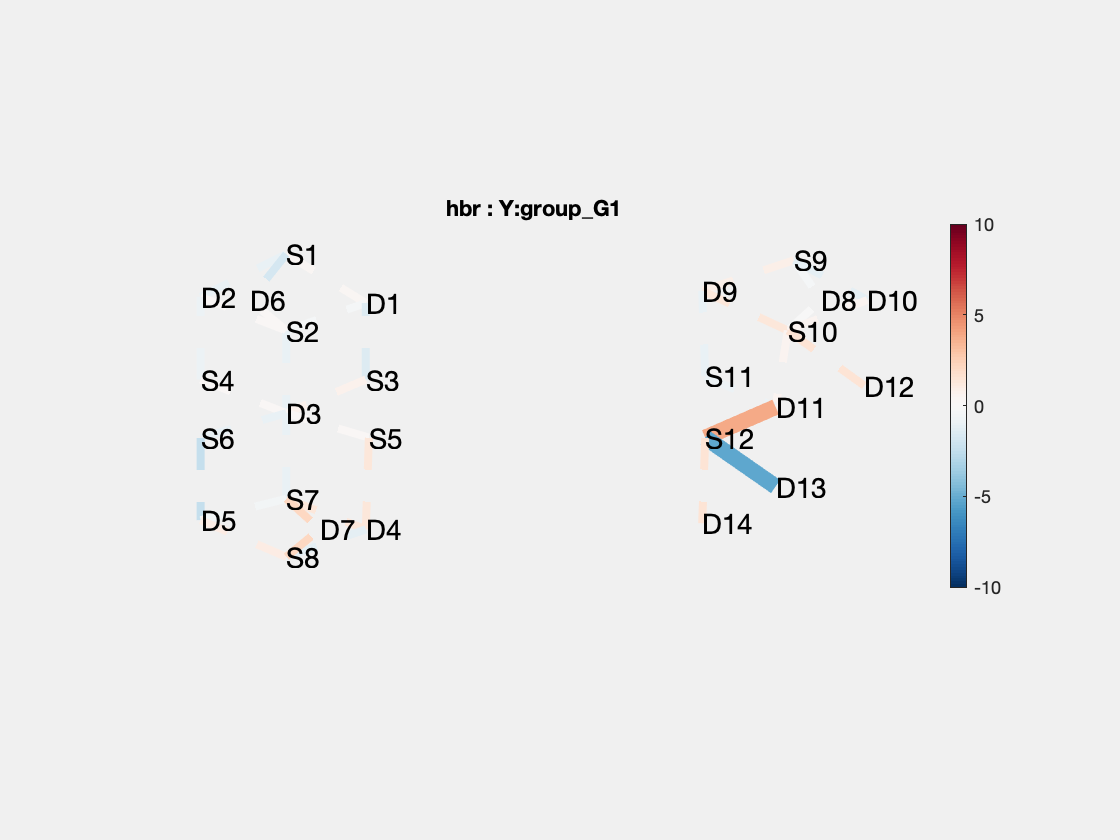

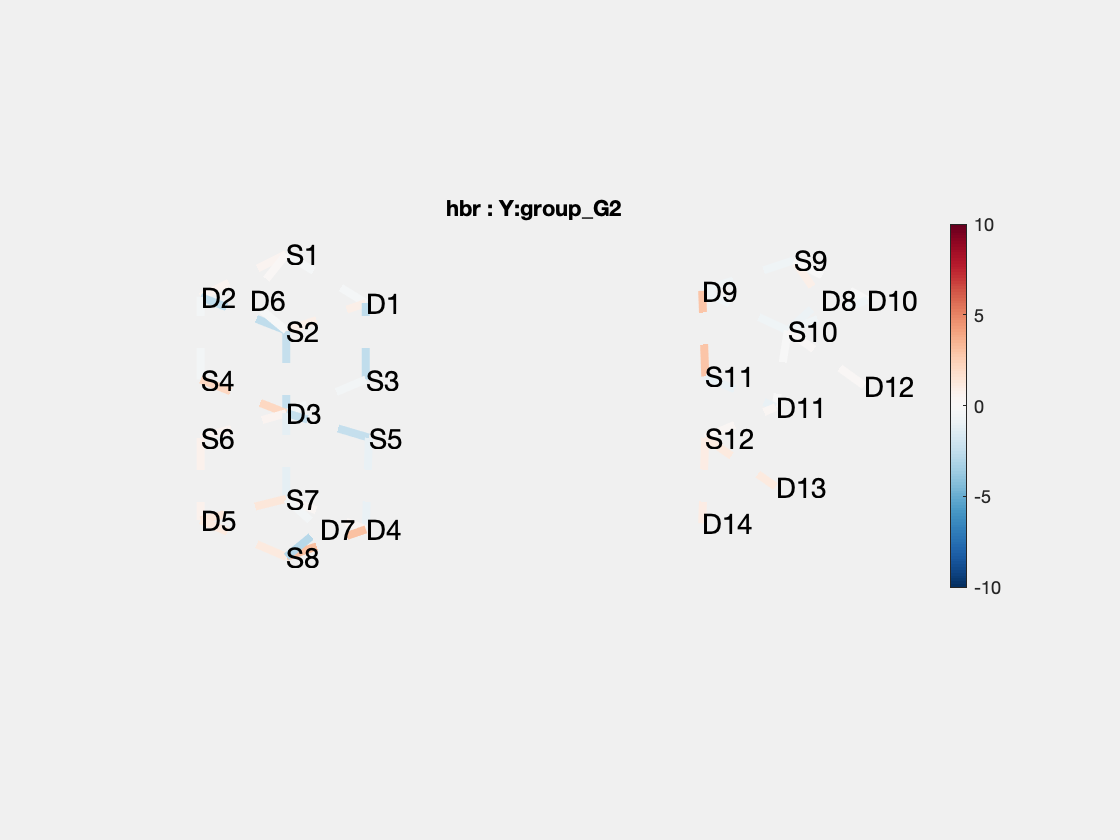

ans =   1×10 Figure array:

    Figure    Figure    Figure    Figure    Figure    Figure    Figure    Figure    Figure    Figure



% You can also use false discovery rate for stat significance
GroupStats.draw('tstat', [-10 10], 'q < 0.05')


% If you want to know the critical value you can use
GroupStats.getCritT('q < 0.05')

ans = 3.5380

% Q is the false-discovery rate (see <https://en.wikipedia.org/wiki/False_discovery_rate> )

% You can also display a table of all stats
disp(GroupStats.table());

    source    detector    type         cond              model             beta           se          tstat       dfe        p             q          power 
    ______    ________    _____    ____________    _________________    ___________    ________    ___________    ___    __________    __________    _______

       1          1       'hbo'    'age'           [1×1 LinearModel]      -0.076144    0.059359        -1.2828    29        0.20973       0.68205    0.34898
       1          1       'hbo'    'X:group_G1'    [1×1 LinearModel]       -0.43648      2.7224       -0.16033    29    

% This is a big table structure, but you can pull all the beta, tstats, etc
% from this table (see matlab >>help table) for information on this class

## Contrasts

We are usually interested in differences between groups or conditions. First, look at what the conditions (regression variables) are:

disp(GroupStats.conditions);

    'X:group_G1'
    'X:group_G2'
    'Y:group_G1'
    'Y:group_G2'
    'age'



% We can see that there are five contasts.

% Next, specify a contrast vector
c = [0 1 0 -1 0];
% This means we want to contrast the 2nd (Y:group1) and 4th (Y:group1)
% conditions.  

% or we can specify a bunch of contrasts:
c = [eye(5);  % all 5 of the original variables
    0 1 0 -1 0; % X - Y for group 1
    0 0 1 0 -1; % X - Y for group 2
    0 1 -1 0 0; % G1 - G2 for X
    0 0 0 1 -1]; % G1 - G2 for Y

% Calculate stats with the ttest function
ContrastStats = GroupStats.ttest(c);
% ContrastStats is yet anouther ChannelStats variable and has all the same methods
% and fields as the other ones we have seen.


% Finally, let's save the figures as eps files for closer inspection and/or
% making manuscript figures. Can also use tif or jpg.
close all;  

folder = [root_dir filesep 'figures'];
ContrastStats.printAll('tstat', [-10 10], 'q < 0.05', folder, 'eps')
% The printAll command also will work for the GroupStats and SubjStats
% variables above.

% You should expect to see X > Y and G1 > G2 for HbO.  Nothing should be
% significant for age since this data was random.

## Region of interest tables

You can manually specify regions of interest. The stats are computed based on the channel-wise covariance informtion. 

          %Src - Det to include in the ROI
MeasList=[1 1;...
          1 2;...
          1 6;...
          2 1;...
          2 2;...
          2 3];
      
Region{1} = table(MeasList(:,1),MeasList(:,2),'VariableNames',{'source','detector'});
%This first region is defined based on src-detectors
 
MeasList=[10 NaN; 11 NaN; 12 NaN];
 Region{2} = table(MeasList(:,1),MeasList(:,2),'VariableNames',{'source','detector'});
%This 2nd region is defined by all detectors connected to sources 10,11,&
%12.  Use NaN to denote all-detectors (or sources);  [NaN NaN]- would give
%the whole probe

MeasList=[NaN 1; NaN 2; NaN 3];
 Region{3} = table(MeasList(:,1),MeasList(:,2),'VariableNames',{'source','detector'});
%This 2nd region is defined by all sources connected to detectors 1,2,3

ROItable=nirs.util.roiAverage(ContrastStats,Region,{'region1','region2','region3'});
disp(ROItable);

       ROI       type            Contrast               Beta          SE       DF       T            p           q        power 
    _________    _____    _______________________    __________    ________    __    ________    _________    _______    _______

    'region1'    'hbo'    'X:group_G1'                   1.6196      1.3169    29      1.2298      0.22865    0.56122    0.35366
    'region1'    'hbr'    'X:group_G1'                  0.43463     0.71439    29     0.60839      0.54766    0.77107    0.45039
    'region2'    'hbo'    'X:group_G1'                   3.2834      2.1223    29      1.5471      0.13267    0.55221    0.32978
    'region2' 


% disp(ROItable)
%          ROI                     Contrast                    Beta          SE         DF        T            p             q     
%     _____________    _________________________________    __________    _________    ____    ________    __________    __________
% 
%     'region1:hbo'    'age'                                 0.0020717    0.0025301    2030      0.8188         0.413         0.531
%     'region2:hbo'    'age'                                 0.0026254    0.0017085    2030      1.5367       0.12453       0.24017
%     'region3:hbo'    'age'                                 0.0022544    0.0037535    2030     0.60061       0.54816       0.62981
%     'region1:hbr'    'age'                                 0.0013405    0.0014723    2030     0.91051       0.36266       0.51536
%     'region2:hbr'    'age'                                 0.0026883    0.0012829    2030      2.0954      0.036255      0.081574
%     'region3:hbr'    'age'                                -0.0015894    0.0030455    2030    -0.52187       0.60182       0.67705
%     'region1:hbo'    'cond_X:group_G1'                        1.2824      0.10411    2030      12.318    1.1241e-33    6.0701e-32
%     'region2:hbo'    'cond_X:group_G1'                       0.19298     0.083797    2030       2.303      0.021381      0.060767
%     'region3:hbo'    'cond_X:group_G1'                        1.5061      0.16778    2030      8.9766    6.2076e-19     1.676e-17
%     'region1:hbr'    'cond_X:group_G1'                      -0.35326      0.06757    2030     -5.2282     1.888e-07    2.5488e-06
%     'region2:hbr'    'cond_X:group_G1'                      0.061871     0.066938    2030      0.9243       0.35544       0.51875
%     'region3:hbr'    'cond_X:group_G1'                      -0.51791      0.12994    2030     -3.9859     6.961e-05    0.00034172

## Saving and loading variables

All the classes above are matlab variables and can be saved and loaded just like any other matlab variables. Note however, that because they use special data classes that are defined by the toolbox (e.g. +nirs namespace) the toolbox needs to be in the path to reload the saved variables.